## HW4 Q1

I tried e = 0.3 and e = 0.7 in this question. The output images look similar but with small differences. Compared to the output of the original mean shift, there are some extra and larger black dots in the new images, mainly appearing around the edge and corner areas. 

Also, black dots in e = 0.7 are larger than those in e = 0.3. Such difference is because as e increases, more values are categorized to the same centroid and skipped during iteration which leads to the decrease of accuracy. All in all, I would say the results matched pretty well to the original.

I think the speedup is worthwhile since it takes much less time to achieve an almost similar result, which will eventually promote the efficiency of image processing when dealing with a large number of images. 

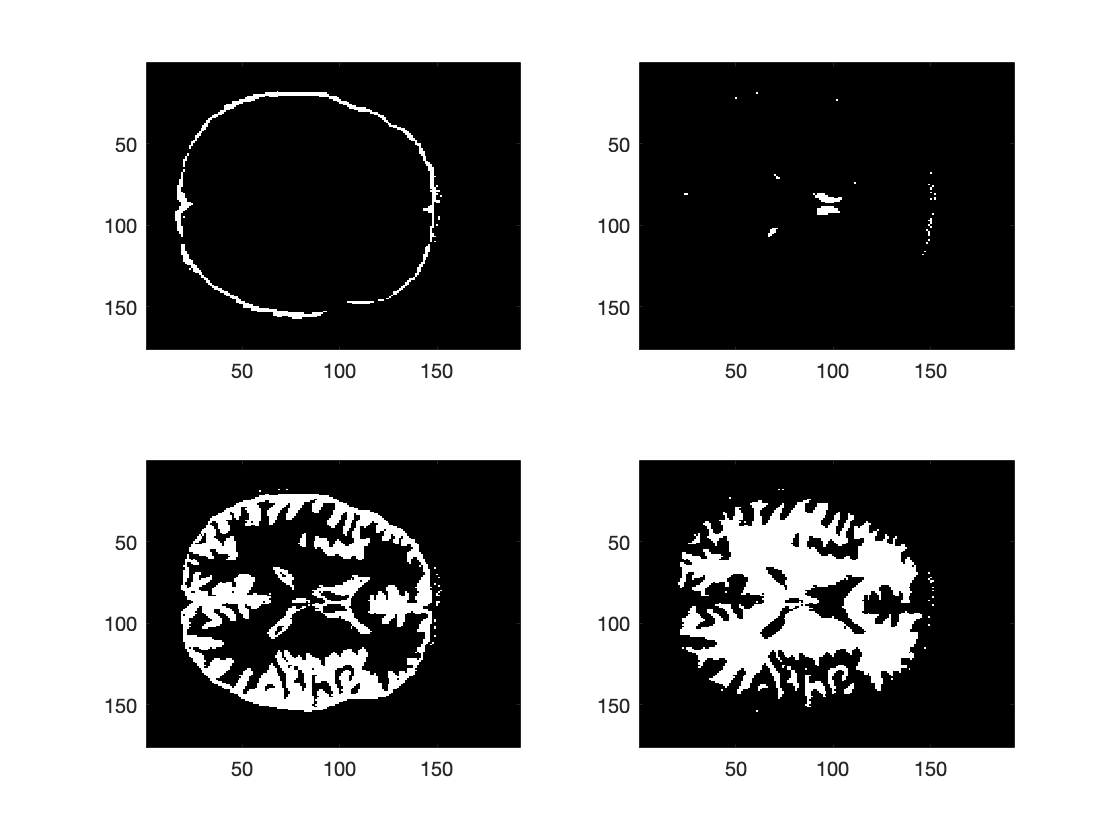

% Quick 1 feature example
dat = [randn(500, 1)*3; randn(500, 1)*4+15];

% Get histogram of density in Matlab

[f, x] = hist(dat, 40);
dx = x(2)-x(1);

%estimate kde in 1D using Epanechnikov kernel
x_val = min(dat):.1:max(dat);
dens_est = zeros(size(x_val));
h=3;
nx = length(dat);

for ind=1:length(x_val)
   val_loop = dat(abs((dat-x_val(ind))/h) <=1); 
   ku = .75*(1-((x_val(ind) - val_loop)/h).^2);
   dens_est(ind) = 1/(nx*h)*sum(ku);
end

% Image segmentation using k-means
file_path = '.';

% data (slice of MRI data: T1 structural image of brain)
load(sprintf('%s/T1.mat', file_path));

% Same, but a T2 image
load(sprintf('%s/T2.mat', file_path));

% To save time, just using a small section of data for illustration
T1_section = double(T1);
T2_section = double(T2);

% put data in vector and remove 0 (0 is background)
keep = T1_section>0 & T2_section>0;
T1_vec = T1_section(keep);
T2_vec = T2_section(keep);

% rescale
T1_vec = (T1_vec-mean(T1_vec))/std(T1_vec);
T2_vec = (T2_vec-mean(T2_vec))/std(T2_vec);

% Run mean shift and plot shifts as we go
radius = 1;
stop_criterion = .01;  % Largest distance allowed between 2
                       % iterations without stopping

seg_feat1 = 0*T1_vec;
seg_feat2 = 0*T2_vec;

board = zeros(length(T1_vec),1);
% e = 0.3
    e = 0.3;
    for loc=1:length(T1_vec)
        if(board(loc) == 1)
            continue;
        end
        cur_feat1 = T1_vec(loc);
        cur_feat2 = T2_vec(loc);
        cur_criterion = 2;
        e_loop = zeros(length(T1_vec),1);
        % Find the convergence point for the single voxel
        while cur_criterion>stop_criterion
        % compute distance for all points vs first
            dist_loop = ((cur_feat1(end) - T1_vec).^2 + (cur_feat2(end) - T2_vec).^2).^.5;
            keep_loop = dist_loop<radius;
            e_loop = e_loop | (dist_loop < radius*e);
            mean_loop_feat1 = mean(T1_vec(keep_loop==1));
            mean_loop_feat2 = mean(T2_vec(keep_loop==1));
            cur_criterion = ((cur_feat1(end) - mean_loop_feat1).^2 + (cur_feat2(end) - mean_loop_feat2).^2).^.5;
            cur_feat1 = [cur_feat1, mean_loop_feat1];
            cur_feat2 = [cur_feat2, mean_loop_feat2];
        end
        seg_feat1(loc) = cur_feat1(end);
        seg_feat2(loc) = cur_feat2(end); 
        seg_feat1(e_loop == 1) = cur_feat1(end);
        seg_feat2(e_loop == 1) = cur_feat2(end);
        board(e_loop == 1) = 1;
        board(loc) = 1;
    end


    % Round and look at unique end points
    unique_vals = unique([round(seg_feat1), round(seg_feat2)], 'rows');

    % create the 3 classes and plot
    seg_vec = 0*T1_vec;
    seg_vec(round(seg_feat1)==-2 & round(seg_feat2)== -3) = 1;
    seg_vec(round(seg_feat1)==-2 & round(seg_feat2)== -2) = 1;
    seg_vec(round(seg_feat1)==-2 & round(seg_feat2)== 3) = 2;
    seg_vec(round(seg_feat1)==0 & round(seg_feat2)== 0) = 3;
    seg_vec(round(seg_feat1)==1 & round(seg_feat2)== 0) = 4;

    seg_img = T1_section;
    seg_img(keep==1) = seg_vec;

    figure
    subplot(2,2,1)
    imagesc(seg_img==1); colormap('gray')
    subplot(2,2,2)
    imagesc(seg_img==2); colormap('gray')
    subplot(2,2,3)
    imagesc(seg_img==3); colormap('gray')
    subplot(2,2,4)
    imagesc(seg_img==4); colormap('gray')
    saveas(gcf,'e3.png');

    %suptitle('e = 0.3')
    
    
% e = 0.7
    e = 0.7;
    for loc=1:length(T1_vec)
        if(board(loc) == 1)
            continue; % skip
        end
        cur_feat1 = T1_vec(loc);
        cur_feat2 = T2_vec(loc);
        cur_criterion = 2;
        e_loop = zeros(length(T1_vec),1);
        % Find the convergence point for the single voxel
        while cur_criterion>stop_criterion
        % compute distance for all points vs first
            dist_loop = ((cur_feat1(end) - T1_vec).^2 + (cur_feat2(end) - T2_vec).^2).^.5;
            keep_loop = dist_loop<radius;
            e_loop = e_loop | (dist_loop < radius*e);
            mean_loop_feat1 = mean(T1_vec(keep_loop==1));
            mean_loop_feat2 = mean(T2_vec(keep_loop==1));
            cur_criterion = ((cur_feat1(end) - mean_loop_feat1).^2 + (cur_feat2(end) - mean_loop_feat2).^2).^.5;
            cur_feat1 = [cur_feat1, mean_loop_feat1];
            cur_feat2 = [cur_feat2, mean_loop_feat2];
        end
        seg_feat1(loc) = cur_feat1(end);
        seg_feat2(loc) = cur_feat2(end); 
        seg_feat1(e_loop == 1) = cur_feat1(end);
        seg_feat2(e_loop == 1) = cur_feat2(end);
        board(e_loop == 1) = 1;
        board(loc) = 1;
    end

    % Round and look at unique end points
    unique_vals = unique([round(seg_feat1), round(seg_feat2)], 'rows');

    % Create the 3 classes and plot
    seg_vec = 0*T1_vec;
    seg_vec(round(seg_feat1)==-2 & round(seg_feat2)== -3) = 1;
    seg_vec(round(seg_feat1)==-2 & round(seg_feat2)== -2) = 1;
    seg_vec(round(seg_feat1)==-2 & round(seg_feat2)== 3) = 2;
    seg_vec(round(seg_feat1)==0 & round(seg_feat2)== 0) = 3;
    seg_vec(round(seg_feat1)==1 & round(seg_feat2)== 0) = 4;

    seg_img = T1_section;
    seg_img(keep==1) = seg_vec;

    figure
    title('e = 0.7');
    subplot(2,2,1)
    imagesc(seg_img==1); colormap('gray')
    subplot(2,2,2)
    imagesc(seg_img==2); colormap('gray')
    subplot(2,2,3)
    imagesc(seg_img==3); colormap('gray')
    subplot(2,2,4)
    imagesc(seg_img==4); colormap('gray')
    saveas(gcf,'e7.png');

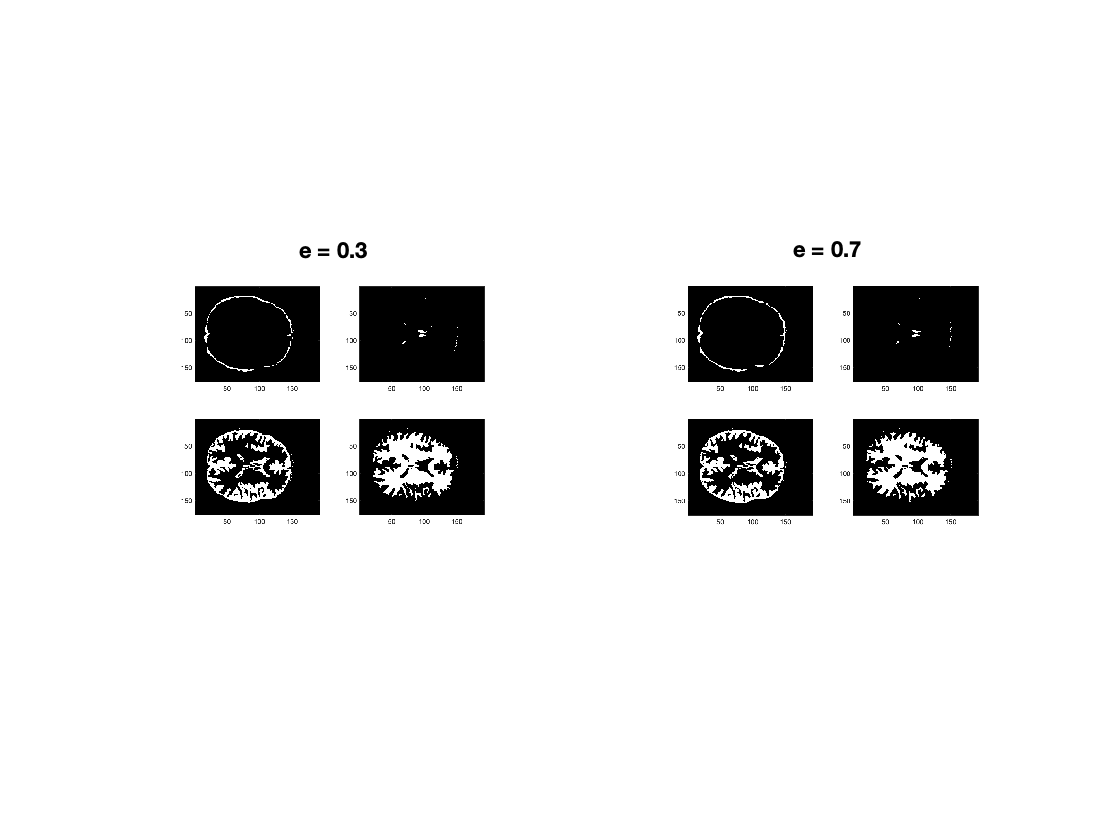

   % suptitle('e = 0.7')
    
e3 = imread('e3.png');
e7 = imread('e7.png');
figure
subplot(1,2,1);
imshow(e3);
title('e = 0.3');
subplot(1,2,2);
imshow(e7);
title('e = 0.7');